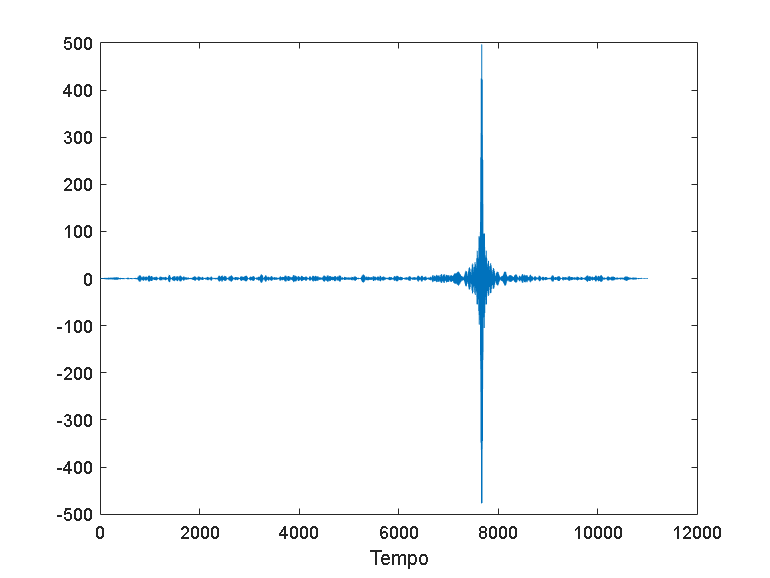

clear, clc, close all;

% Parâmetros da transmissão
param.duracao_pulso = 10e-6; % s
param.largura_banda = 3e6; % Hz
param.freq_central = 30e6; % Hz
param.taxa_amostragem = 100e6; % Hz

% Parâmetros da recepção
param.posicao = 1e4; % m
param.velocidade = 100; % m/s
param.intervalo_repeticao = 1e-4; % s
param.tempo_total = 1e-5; % s
param.SNR_dB = 3; % dB

param.max_riple = 1;
param.atenuacao = 30; %dB
param.decimacao = 10;


% Gerar sinal de transmissão
sinal_transmissao = transmissao(param);

% Suponha que N seja o número de sinais recebidos durante uma passagem de antena
N = 1;

% Crie uma matriz vazia para armazenar os sinais recebidos
buffer_sinais_recebidos = [];

% Loop para receber e armazenar os sinais
for i = 1:N
    % Gerar sinal de recepção
    sinal_recepcao = recepcao(sinal_transmissao, param);

    % Filtragem do sinal recebido
    [sinal_centralizado, sinal_filtrado, sinal_decimado] = filtragem(sinal_recepcao, param);
    
    % Fitro casado
    sinal_filtro_casado = filtro_casado(sinal_transmissao, sinal_recepcao, param);
    
    % Armazenar sinal recebido na matriz
    buffer_sinais_recebidos(:, i) = sinal_filtro_casado.sinal;
end

% Realizar a integração em tempo lento
sinal_integrado = sum(buffer_sinais_recebidos, 2) / N;

% Agora você pode processar o sinal integrado como desejar
% Por exemplo, plotar o sinal integrado
figure;
plot(sinal_integrado);
xlabel('Tempo');

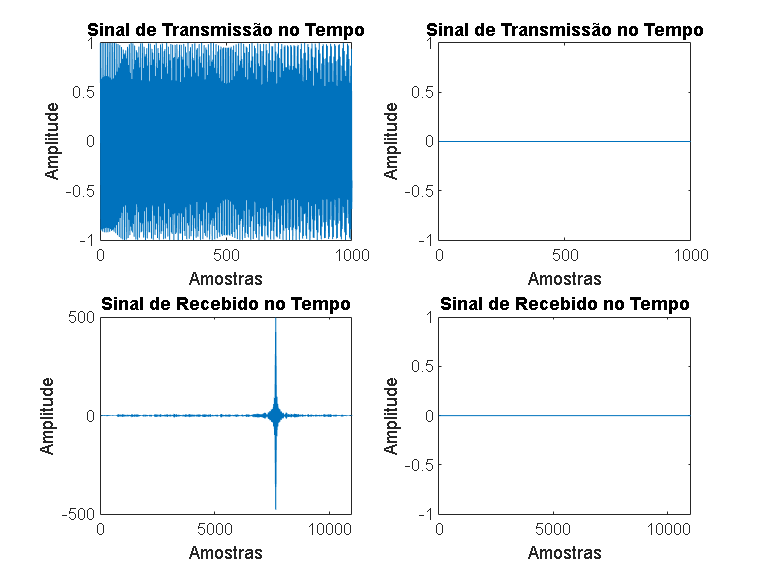



% Plotar os sinais no tempo e na frequência e seus espectogramas
figure;
subplot(2,2,1);
plot(real(sinal_transmissao.sinal));
title('Sinal de Transmissão no Tempo');
xlabel('Amostras');
ylabel('Amplitude');
subplot(2,2,2);
plot(imag(sinal_transmissao.sinal));
title('Sinal de Transmissão no Tempo');
xlabel('Amostras');
ylabel('Amplitude');
subplot(2,2,3);
plot(real(sinal_integrado));
title('Sinal de Recebido no Tempo');
xlabel('Amostras');
ylabel('Amplitude');
subplot(2,2,4);
plot(imag(sinal_integrado));
title('Sinal de Recebido no Tempo');
xlabel('Amostras');
ylabel('Amplitude');

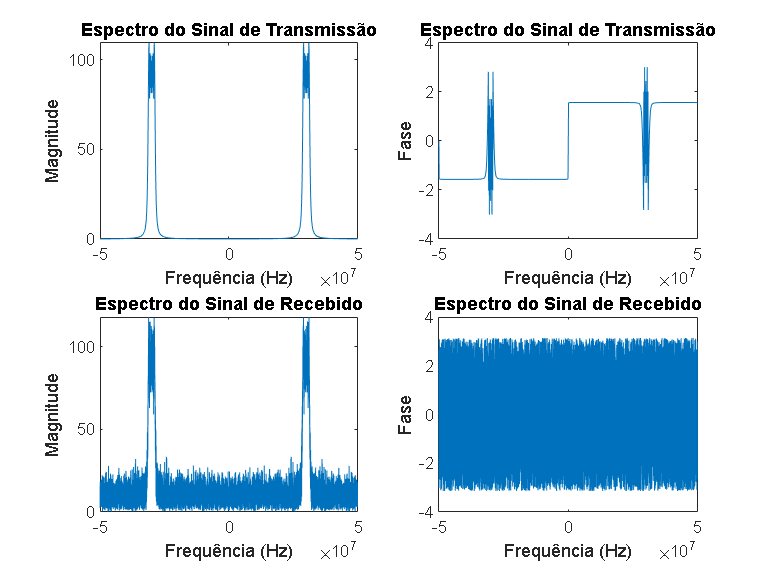


figure;
subplot(2,2,1);
plot(sinal_transmissao.freq_range, sinal_transmissao.modulo)
title('Espectro do Sinal de Transmissão');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
subplot(2,2,2);
plot(sinal_transmissao.freq_range, sinal_transmissao.fase)
title('Espectro do Sinal de Transmissão');
xlabel('Frequência (Hz)');
ylabel('Fase');
subplot(2,2,3);
plot(sinal_recepcao.freq_range, sinal_recepcao.modulo)
title('Espectro do Sinal de Recebido');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
subplot(2,2,4);
plot(sinal_recepcao.freq_range, sinal_recepcao.fase);
title('Espectro do Sinal de Recebido');
xlabel('Frequência (Hz)');
ylabel('Fase');

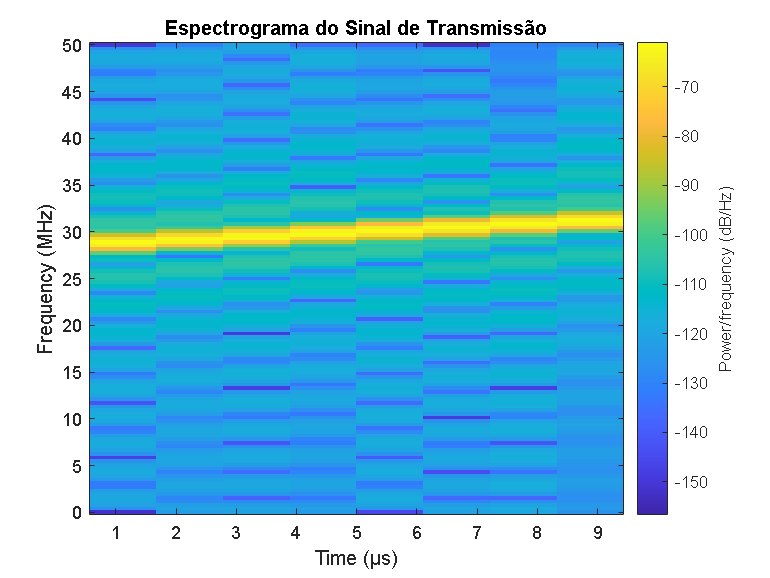


figure;
spectrogram(sinal_transmissao.sinal, [], [], [], param.taxa_amostragem, 'yaxis');
title('Espectrograma do Sinal de Transmissão');

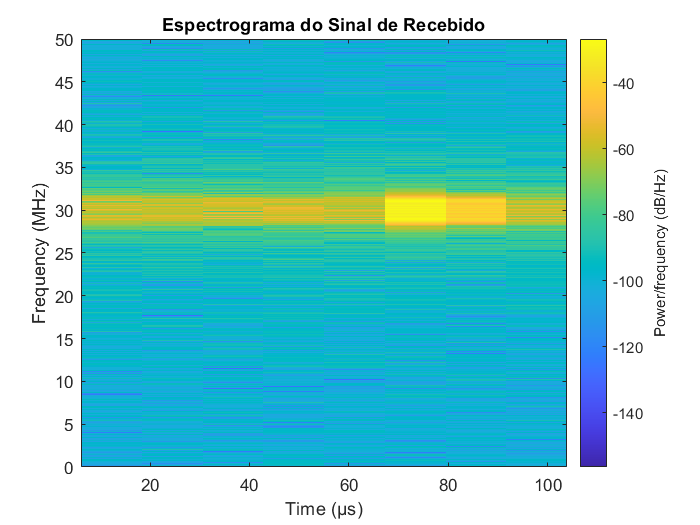

figure;
spectrogram(sinal_integrado, [], [], [], param.taxa_amostragem, 'yaxis');
title('Espectrograma do Sinal de Recebido');

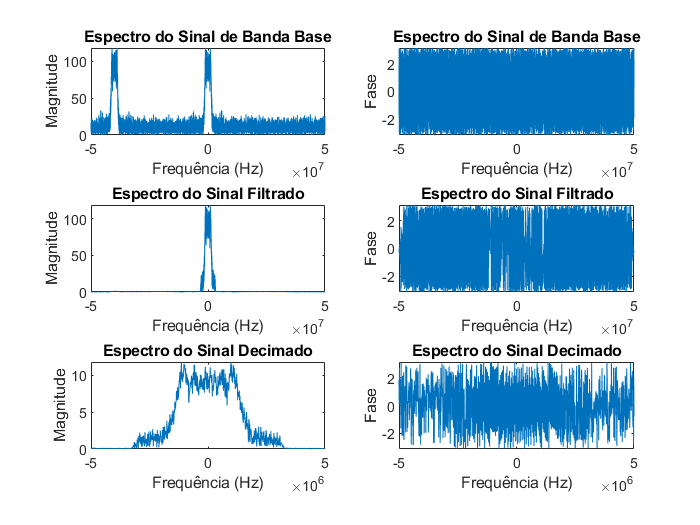


figure
subplot(3,2,1);
plot(sinal_centralizado.freq_range, sinal_centralizado.modulo)
title('Espectro do Sinal de Banda Base');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
subplot(3,2,2);
plot(sinal_centralizado.freq_range, sinal_centralizado.fase)
title('Espectro do Sinal de Banda Base');
xlabel('Frequência (Hz)');
ylabel('Fase');
subplot(3,2,3);
plot(sinal_filtrado.freq_range, sinal_filtrado.modulo)
title('Espectro do Sinal Filtrado');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
subplot(3,2,4);
plot(sinal_filtrado.freq_range, sinal_filtrado.fase)
title('Espectro do Sinal Filtrado');
xlabel('Frequência (Hz)');
ylabel('Fase');
subplot(3,2,5);
plot(sinal_decimado.freq_range, sinal_decimado.modulo)
title('Espectro do Sinal Decimado');
xlabel('Frequência (Hz)');
ylabel('Magnitude');
subplot(3,2,6);
plot(sinal_decimado.freq_range, sinal_decimado.fase)
title('Espectro do Sinal Decimado');
xlabel('Frequência (Hz)');
ylabel('Fase');

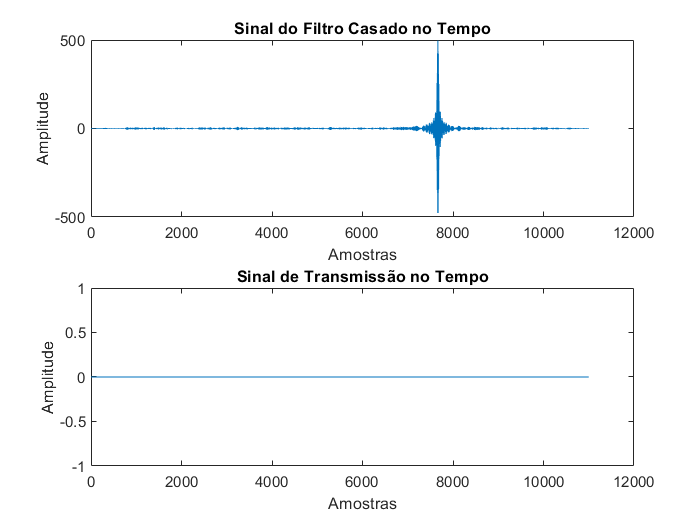


figure
subplot(2,1,1);
plot(real(sinal_filtro_casado.sinal));
title('Sinal do Filtro Casado no Tempo');
xlabel('Amostras');
ylabel('Amplitude');
subplot(2,1,2);
plot(imag(sinal_filtro_casado.sinal));
title('Sinal de Transmissão no Tempo');
xlabel('Amostras');
ylabel('Amplitude');